# Computing $\pi$... Simscape Multibody Style

On this $\pi$ day 2024, I decided to tag along with Mike Croucher from [The MATLAB Blog](https://blogs.mathworks.com/matlab) and show one way to compute $\pi$.

While Mike went for advanced maneuvers involving [Parallel Computing Toolbox](https://www.mathworks.com/products/parallel-computing.html), [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html) and even [Quantum Computing](https://www.mathworks.com/products/quantum-computing.html), I decided to go with the way our ancestors would have done thousands of years ago: by rolling a cylinder. See [this WikiHow article](https://www.wikihow.com/Calculate-Pi) for more details.

## The Model

Using Simscape Multibody, I connected a [Planar Joint](https://www.mathworks.com/help/releases/R2023b/sm/ref/planarjoint.html) and a [Cylinder Solid](https://www.mathworks.com/help/releases/R2023b/sm/ref/cylindricalsolid.html) together. I let the Cylinder fall on an [Infinite Plane](https://www.mathworks.com/help/releases/R2023b/sm/ref/infiniteplane.html) and used the [Spatial Contact Force](https://www.mathworks.com/help/releases/R2023b/sm/ref/spatialcontactforce.html) block to compute the contact dynamic between those two:

mdl = 'ComputePi';
open_system(mdl);

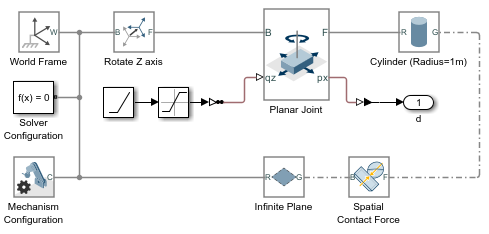

I used [Motion Actuation](https://www.mathworks.com/help/releases/R2023b/sm/ug/joint-actuation.html?s_tid=doc_srchtitle#bt323b1-1) to roll the cylinder by 360 degrees and sensed by how much it had translated. I was then able to compute $\pi$ using:


$$\pi =\frac{d}{2r}$$


where $d$ is the distance travelled and $r$ is the radius of the cylinder. 

in = Simulink.SimulationInput(mdl);
out = sim(in);
r = 1;  % Cylinder radius;
d = out.yout{1}.Values.Data(end);
pi_estimate = d/(2*r)

pi_estimate = 3.0956

Because the cylinder slipped a bit on the ground, I did not get a very accurate result, but it's probably representative of the result you would get if you had tried computing $\pi$ that way a few thousand years ago.

Here is the [Mechanics Explorer](https://www.mathworks.com/help/releases/R2023b/sm/ref/mechanicsexplorer-app.html) animation for this simulation:

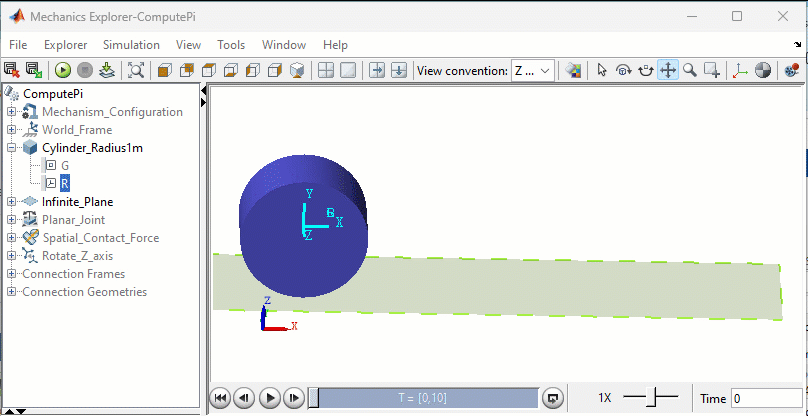

## Now it's your turn

Hopefully, you can find more accurate ways to compute $\pi$. If you need to model cylinders rolling on the ground, try opening the model used for this blog post in [MATLAB Online](https://matlab.mathworks.com/) by clicking on this banner:

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2024_03_14_ComputingPi/2024_03_14_ComputingPi.prj)